# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

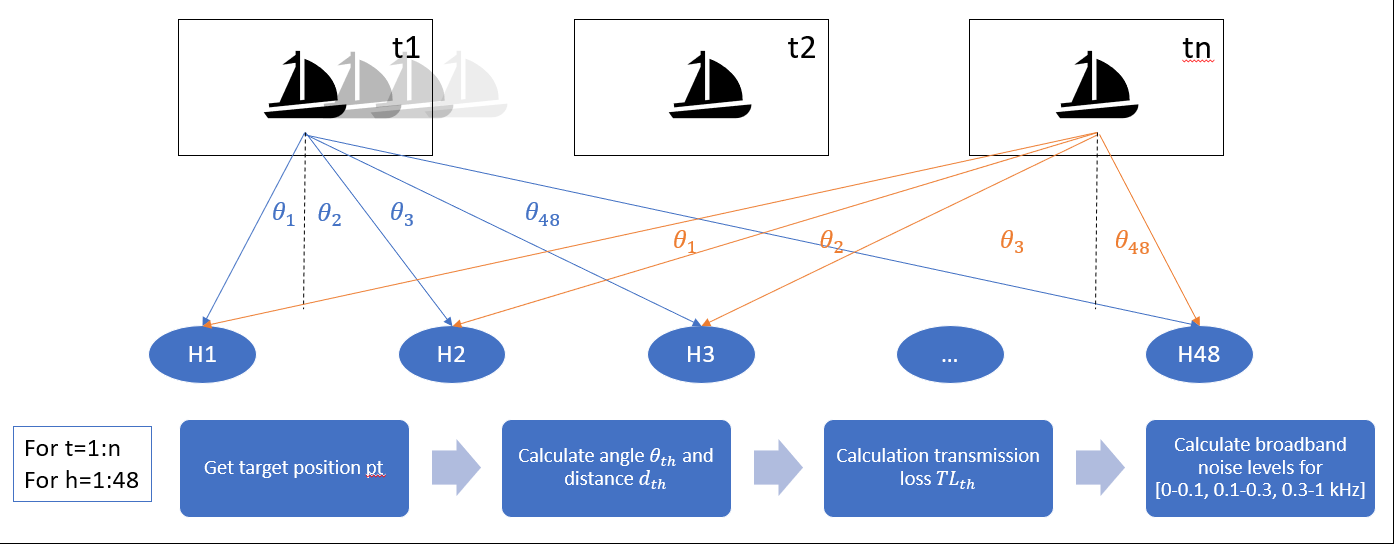

## Initialize

clearvars

#### Flip switches

sampling = 'full';
plotSpectrogram = 'no';
plotSpectra = 'no';
plotShipTrack = 'yes';
plotBearingHistory = 'yes';
plotSpatialSummary = 'yes';
plotIntTrack = 'yes';
plotAspects = 'yes';

#### Set parameters

Num1secSeg = 5;                             %number of segments for averaging
TimeIntSec = 3;                             %time-difference [sec] btw. beginning of segments
fstartind = 10;                             %10Hz for computing received levels
fstopind = 1001;                            %1000Hz for computing received levels
NumRec = 48;                                %number of hydrophone channels
BinWidth = 1;                               %processing bin width [Hz]
RefRecInd = 24;                             %reference hydrophone for spatial center
nArrays = 2;                                %number of hydrophone arrays
km2m = 1000;                                %convert km to m
km2kts = 1.9434;                            %convert km to kts
par.spread = 20;                            %spreading coefficient

## Acoustic data pre-processing

### Define parameters

sens = 194.5;                   % (nominal) dB re 1V/uPa
cal = 10^(sens/20);             % hydrophone calibration
gain.amp = 0;%-70;                 % Amplifier gain 70 dB (adjustable), A/D -8 dB (I don't think gain is correct - confirm A/D)
gain.adc = 0; %20*log(5/(2^16));    % 1 Vrms = 16 bit peak-to-peak --> could also be +/- 1 floating point range (20log(2.0/5.0))
gain.fft = 0;                   % FFT gain is applied in spectra (2/NFFT)

### Load acoustic data

dFile = 'allCh.wav';           % Select the 48-ch (allCh) or 1-ch (singleCh) file
NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\proc',dFile);
%NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\OcEnd\20150830_AAA2\west_aaa2_20150830_094520_00_0010.wav');
[x,fs] = audioread(NWFile);  % What is this signal? Volts? --> need to convert to dB (x/sens)
SegLengthSamples = BinWidth*fs;
DataLengthSamples = Num1secSeg*SegLengthSamples;

### Downsample acoustic data (optional)

switch sampling
    case 'full'
        nFactor = 1;
        disp('sampling full band')
    case 'downsample'
        nFactor = 1000;
        y = downsample(x,nFactor); %downsample or decimate?
        x = y;
        clear y
end

sampling full band


[nsam,nch] = size(x);

### Generate time vector

startTime = datetime(2015,8,30,9,26,43);  % OcEnd - west_aaa2_20150830_091724_00_0007
StartTime = datenum(startTime);
endTime = startTime + seconds(length(x(:,1))/fs);
EndTime = datenum(endTime);
TimeVector = StartTime:TimeIntSec/(3600*24):EndTime;
NumSpec = length(TimeVector);

### Transfer function for array

One-sided to save memory

fRspectra = fs/2*linspace(0,1,SegLengthSamples/2+1);    %frequencies [Hz]
G = 10^(sens/20);                                       %Array transfer function is flat across frequencies

## Received spectra with 1 Hz bins

Paper: Each of the eight pressure time series was divided into consecutive, non-overlapping segments with a length of 1 s (200 000 samples).

S =  cell(NumRec,1);   % Spectra for each array elements
for RecInd=1:NumRec
    S{RecInd} = zeros(NumSpec-2,SegLengthSamples/2+1);  % 48 x fs  (one-sided)
end

### Loop to read data piece by piece

for EventIndex = 1:(NumSpec-2)
    for RecInd=1:NumRec
        data = x(TimeIntSec*fs*(EventIndex-1)+1:...
            TimeIntSec*fs*(EventIndex-1)+DataLengthSamples,RecInd);
        NumSeg = floor(length(data)/SegLengthSamples);

### Compute received spectra

Apply a two-sided FFT to each segment to yield a frequency bin spacing of 1 Hz. The magnitude squared values of the complex FFT coefficients for the positive frequencies were multiplied by 2/NFFT^2 to account for the processing gain of the FFT.

Compute onesided spectra and calibrate with HARP specific hydrophone transfer functions

        X = fft(reshape(data(1:NumSeg*SegLengthSamples),...
            SegLengthSamples,NumSeg));
        S{RecInd}(EventIndex,:) = ...
            (sum(2*abs(X(1:SegLengthSamples/2+1,:)).^2,2)*G^2)...
            /(NumSeg*SegLengthSamples*fs);
    end
    

#### Display progress

    if mod(EventIndex,round(NumSpec/10))==0
        disp([num2str(round(100*EventIndex/NumSpec)) '% done'])
    end
end

10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done


### Correct for A/D and pre-amp gain

gain.total = 10^((gain.amp+gain.adc+gain.fft)/10);    %

### Plot spectrograms

switch plotSpectrogram
    case 'no'
    case 'yes'
        FontSizeNumber=14;
        for RecInd=1:NumRec
            figure;
            %RecInd = RefRecInd;
            imagesc(TimeVector,fRspectra,10*log10(S{RecInd}).');
            title(['Spectrogram of Ocean Endeavour from Hph' num2str(RecInd)],'FontSize',FontSizeNumber)
            axis xy;
            h = colorbar;%caxis([50 130])
            set(get(h,'ylabel'),'string','RL [dB re 1\muPa//Hz]',...
                'FontSize',FontSizeNumber);
            datetick('x','keeplimits');
            xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')],...
                'FontSize',FontSizeNumber)
            ylabel('Frequency [Hz]','FontSize',FontSizeNumber)
            ylim([0 1000])
            set(gca, 'FontSize',FontSizeNumber)
        end
end

## Plot average spectra

switch plotSpectra
    case 'no'
    case 'yes'
        figure
        NumLinesPlot = 4;
        FontSizeNumber = 8;
        NumSubPlots = ceil(NumRec/NumLinesPlot);
        colorarray = hsv(NumRec);
        for RecInd=1:NumRec
            SubPlotInd = floor(RecInd/(NumLinesPlot+1))+1;
            subplot(NumSubPlots,1,SubPlotInd)
            plot(fRspectra,10*log10(sum(S{RecInd})/NumSpec),...
                'Color',colorarray(RecInd,:));
            hold on
            %ylim([60 130])
            %xlim([5 100])
            grid on
            if SubPlotInd == 1
                title(['Spectra time-averaged over '...
                    num2str((TimeVector(end)-TimeVector(1))*24*60) 'min'],'FontSize',FontSizeNumber)
            end
            ylabel('RL [dB re 1\muPa^2//Hz]','FontSize',FontSizeNumber)
            xlabel('f [Hz]','FontSize',FontSizeNumber)
        end
end

## Compute received levels

RLship = zeros(NumRec,NumSpec-2);       %broad band received level [dB]

for RecInd = 1:NumRec
    for index=1:NumSpec-2
        %compute source level from spectrum for beam angle
        RLship(RecInd,index) = 10*log10(trapz(fRspectra(fstartind:fstopind),...
            (S{RecInd}(index,fstartind:fstopind))));%...
    end
end
RLship = (RLship+gain.total)';

## Spatial data processing

#### Load array locations

load arrays_lat-long
% array1=table2array(array1(:,1:3));
% array2=table2array(array2(:,1:3));
A{1}=table2cell(array1);
A{2}=table2cell(array2);

### Load AIS file

Load - sync to spec - calc TL - calc SL - 

m = matfile('byShip.mat');
AIS = m.Oc_End; %m.Heb_Sky;
AIS = sortrows(AIS,'datetime','ascend');
mmsi = AIS.mmsi(1);
AIS.mmsi = []; AIS.rate_of_turn = []; AIS.hdg = [];  % eliminate unused vars
AIStime = table2timetable(AIS);  % might need to make all of this a structure
AIStimeRange = timerange((startTime),(endTime-seconds(6)));  %because integration periods
AIStime = AIStime(AIStimeRange,:);

### Synchronize spectral and spatial data

Make RL and TL same length and combine in time 

timeVector = datetime(TimeVector(1:length(S{1}(:,1))),'ConvertFrom','datenum')';
RLtime = timetable(timeVector,RLship);
SPL = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(3)); %'KeepOriginalTimes',true
SPL = SPL(1:height(RLtime),:); %[RLsync,AISsync] = synchronize(RLtime,AIStime,'regular','linear','TimeStep',seconds(30));

### Calculate ranges along ship track

% [R1,R2] = calcDist(SPL.lat, SPL.long, array1(:,1:2), array2(:,1:2));
% SPL = addvars(SPL,R1,R2);
[R1,R2] = calcDist(SPL.lat, SPL.long, [array1.lat array1.long], [array2.lat array2.long]);
SPL = addvars(SPL,R1,R2);

### Calculate CPA range and time

[rangeCPA_1,timeCPA_1] = min(R1(:,1,1));
[rangeCPA_2,timeCPA_2] = min(R2(:,1,1));
specCPA = 'CPA range AAA1 = %4.2f km and AAA2 = %4.2f km';
fprintf(specCPA,rangeCPA_1,rangeCPA_2);

CPA range AAA1 = 2.04 km and AAA2 = 1.33 km

### Plot ship track vs array

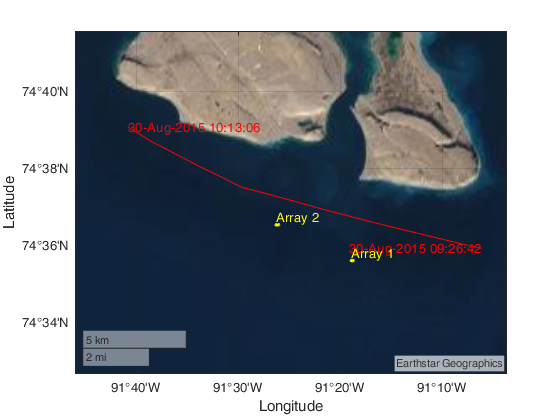

switch plotShipTrack
    case 'no'
    case 'yes'
        figure
        geoplot([SPL.lat], [SPL.long],'r-',...
            [array2.lat],[array2.long],'y.',...
            [array1.lat],[array1.long],'y.')
        text(SPL.lat(1),SPL.long(1),datestr(SPL.timeVector(1)),...
            'HorizontalAlignment','right',"Color",'r');
        text(SPL.lat(end),SPL.long(end),datestr(SPL.timeVector(end)),...
            'HorizontalAlignment','left',"Color",'r');
        text(array1.lat(1),array1.long(1),'Array 1',...
            'VerticalAlignment','bottom',"Color",'y');
        text(array2.lat(1),array2.long(1),'Array 2',...
            'VerticalAlignment','bottom',"Color",'y');
        %geobasemap colorterrain
        %[SPL.lat], [SPL.long],'b*',...
        geobasemap satellite
end

### Plot bearing histogram of ranges

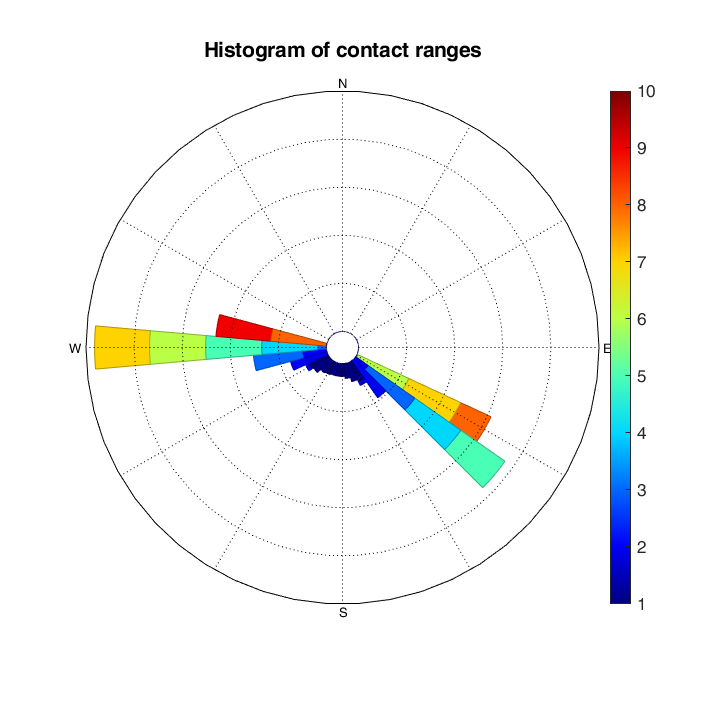

switch plotBearingHistory
    case 'no'
    case 'yes'
        rangeRoser(R2(:,1,2), R2(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)');
        set(gca,'FontSize',14);
end

#### Determine look angle (aspect)

SPL.aspect2 = SPL.crs - SPL.R2(:,:,2);
SPL.rads2 = deg2rad(SPL.aspect2);
SPL.aspect1 = SPL.crs - SPL.R1(:,:,2);
SPL.rads1 = deg2rad(SPL.aspect1);

### Plot ship aspects over track

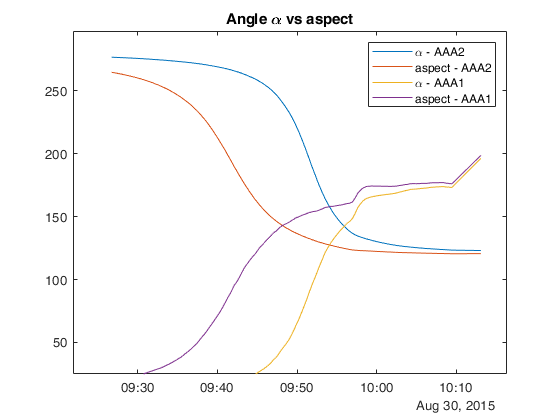

switch plotAspects
    case 'no'
    case 'yes'
        figure
        plot(SPL.timeVector,SPL.R2(:,RefRecInd,2))
        hold on
        plot(SPL.timeVector,SPL.R1(:,RefRecInd,2))
        plot(SPL.timeVector,SPL.aspect2(:,RefRecInd))
        plot(SPL.timeVector,SPL.aspect1(:,RefRecInd))
        title({'Angle \alpha vs aspect'})
        legend('\alpha - AAA2','aspect - AAA2','\alpha - AAA1','aspect - AAA1')
end

### Plot time resolution of AIS data, speed and range history of contact

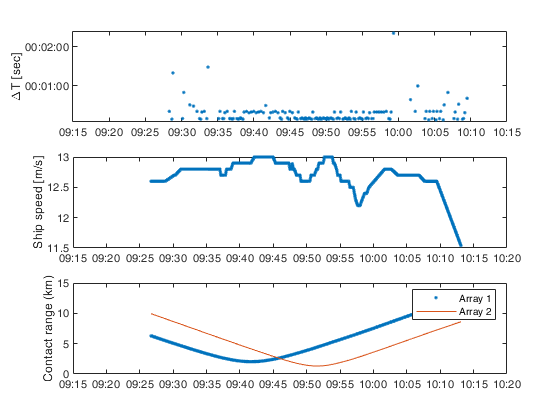

switch plotSpatialSummary
    case 'no'
    case 'yes'
        figure
        subplot(3,1,1)
        plot(AIStime.datetime(1:end-1),diff(AIStime.datetime),'.');
        datetick('x')
        ylabel('\DeltaT [sec]')
        subplot(3,1,2)
        plot(SPL.timeVector,SPL.speed_over_ground,'.');
        datetick('x')
        ylabel('Ship speed [m/s]')
        subplot(3,1,3)
        plot(SPL.timeVector,R1(:,RefRecInd,1),'.');
        hold on
        plot(SPL.timeVector,R2(:,RefRecInd,1),'-')
        datetick('x')
        ylabel('Contact range (km)')
        legend('Array 1','Array 2')
end

### Transform AIS lats/longs to x-y   

SPL.vx = zeros(height(SPL),1);
SPL.vy = zeros(height(SPL),1);
SPL.v = zeros(height(SPL),1);

[SPL.x, SPL.y] = latlon2xy(SPL.lat,SPL.long,...
    array2.lat(RefRecInd),array2.long(RefRecInd));

[array1.x, array1.y] = latlon2xy(array1.lat(:),array1.long(:),...
    array2.lat(RefRecInd),array2.long(RefRecInd));
[array2.x, array2.y] = latlon2xy(array2.lat(:),array2.long(:),...
    array2.lat(RefRecInd),array2.long(RefRecInd));
arrays = [array1.x array1.y -1/km2m*array1.depth];
arrays(:,:,2) = [array2.x array2.y -1/km2m*array2.depth];  %negative depth

### Calculate x and y components of ship speed

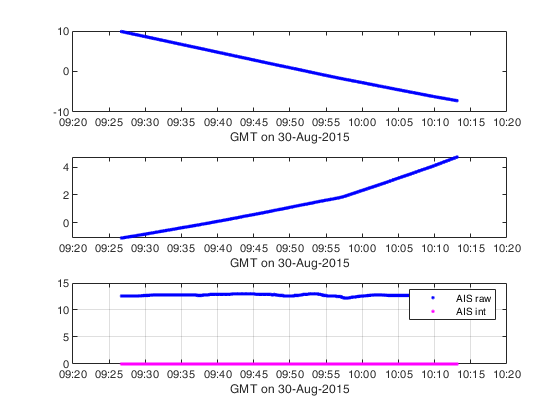

SPL.vx(1:end-1) = diff(SPL.x)./(diff(datenum(SPL.timeVector)*24*3600)); %km/s
SPL.vx(end) = SPL.vx(end-1);
SPL.vy(1:end-1) = diff(SPL.y)./(diff(datenum(SPL.timeVector)*24*3600)); %km/s
SPL.vx(end) = SPL.vx(end-1);
SPL.v = sqrt(SPL.vx.^2 + SPL.vy.^2); %km/s

switch plotIntTrack
    case 'no'
    case 'yes'
        figure;
        subplot(3,1,1)
        plot(SPL.timeVector,SPL.x,'.b');
        datetick('x','keeplimits');
        xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);
        subplot(3,1,2)
        plot(SPL.timeVector,SPL.y,'.b');
        datetick('x','keeplimits');
        xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);
        subplot(3,1,3)
        plot(SPL.timeVector,SPL.speed_over_ground,'.b');
        hold on
        plot(SPL.timeVector,km2kts*SPL.v,'.m')
        datetick('x','keeplimits');
        xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);
        legend('AIS raw','AIS int')
        %ylim([0 15])
        grid on
end

### Compute radiation pattern

alpha = zeros(NumRec,NumSpec-2,nArrays);        %horizontal angle [deg]
phi = zeros(NumRec,NumSpec-2,nArrays);          %vertical angle [deg]
R = zeros(NumRec,NumSpec-2,nArrays);            %slant range [m]
SL.broadband = zeros(NumRec,NumSpec-2); %broadband source level [dB]
SL.ALL = cell(NumRec,1);                %source spectra level [dB]

for RecInd = 1:NumRec
    for index=1:NumSpec-2
        for arrayIndex = 1:nArrays
            
            %compute beam angles alpha and phi
            thetax=0;               % roll angle of Zc =  rotates beampattern around (0deg,0deg)
            thetay = 0;
            thetaz = atan2(SPL.vy(index),SPL.vx(index));
            Rx = [1 0 0; 0 cos(thetax) sin(thetax); 0 -sin(thetax) cos(thetax)];
            Ry = [cos(thetay) 0 sin(thetay); 0 1 0; -sin(thetay) 0 cos(thetay)];
            Rz = [cos(thetaz) sin(thetaz) 0; -sin(thetaz) cos(thetaz) 0; 0 0 1];
            b = arrays(RecInd,:,arrayIndex)...
                - [SPL.x(index) SPL.y(index) 0];
            bprime = Rx*Ry*Rz*b.';
            
            alpha(RecInd,index,arrayIndex) =180*atan2(bprime(2),bprime(1))/pi;
            phi(RecInd,index,arrayIndex) = 180*atan2(bprime(3),norm(bprime(1:2)))/pi;
            
            %slant range of each ship location
            R(RecInd,index,arrayIndex) = sqrt((SPL.x(index)-arrays(RecInd,1,arrayIndex)).^2 + ...
                (SPL.y(index)-arrays(RecInd,2,arrayIndex)).^2 + arrays(RecInd,3,arrayIndex).^2);
            
            %compute source level from spectrum for beam angle
            SL.broadband(RecInd,index) = ...
                RLship(index,RecInd) + par.spread*log10(R(RecInd,index,arrayIndex));  %SL = RL + TL
            SL.ALL{RecInd}(index,:) = ...
                10*log10(S{RecInd}(index,:))+par.spread*log10(R(RecInd,index,arrayIndex));
        end
    end
end


### Plot ship aspects over track

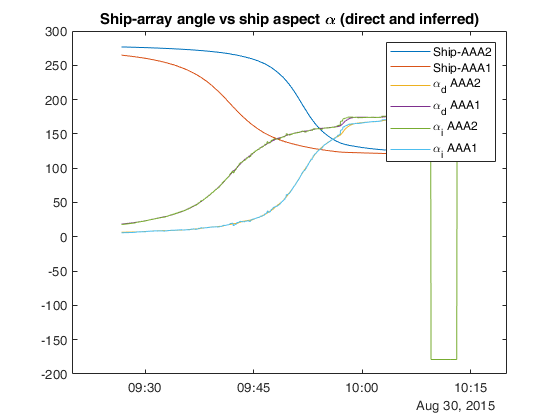

switch plotAspects
    case 'no'
    case 'yes'
        figure
        plot(SPL.timeVector,SPL.R2(:,RefRecInd,2))
        hold on
        plot(SPL.timeVector,SPL.R1(:,RefRecInd,2))
        plot(SPL.timeVector,SPL.aspect2(:,RefRecInd))
        plot(SPL.timeVector,SPL.aspect1(:,RefRecInd))
        plot(SPL.timeVector,alpha(RefRecInd,:,1)')
        plot(SPL.timeVector,alpha(RefRecInd,:,2)')
        title({'Ship-array angle vs ship aspect \alpha (direct and inferred)'})
        legend('Ship-AAA2','Ship-AAA1','\alpha_d AAA2','\alpha_d AAA1',...
            '\alpha_i AAA2','\alpha_i AAA1')
end

## Investigate lobing pattern

### Plot broadband lobing pattern

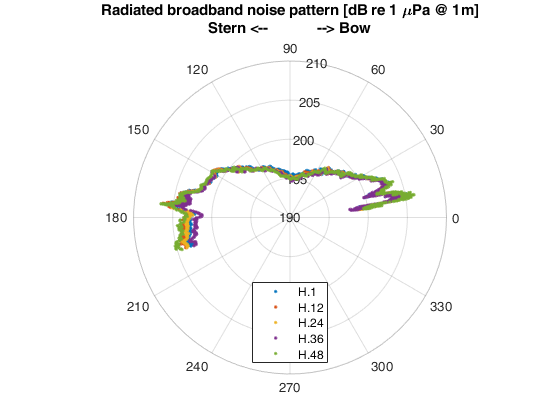

% figure
% polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
figure
polarscatter(SPL.rads2(:,1)',SL.broadband(1,:),'.')
rlim([190 210])
title({'Radiated broadband noise pattern [dB re 1 \muPa @ 1m]';...
    'Stern <--            --> Bow'})
if NumRec == 48
    hold on
    polarscatter(SPL.rads2(:,12)',SL.broadband(12,:),'.')
    polarscatter(SPL.rads2(:,24)',SL.broadband(24,:),'.')
    polarscatter(SPL.rads2(:,36)',SL.broadband(36,:),'.')
    polarscatter(SPL.rads2(:,48)',SL.broadband(48,:),'.')
    legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end

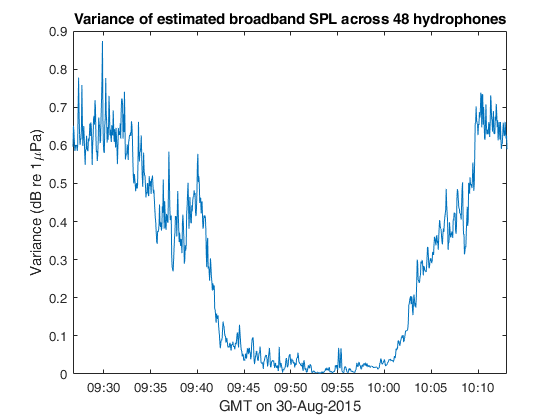

%plotBBsurface(zdata1, xdata1, ydata1)
figure
plot(SPL.timeVector,var(SL.broadband))
xlim([min(SPL.timeVector) max(SPL.timeVector)]);
datetick('x','keeplimits');
title('Variance of estimated broadband SPL across 48 hydrophones')
xlabel(['GMT on ' datestr(TimeVector(1),'dd-mmm-yyyy')]);
ylabel('Variance (dB re 1\muPa)');

### Plot narrowband lobing pattern for (542 - 549 Hz) and (376 - 381 Hz)

Find max SL between 540 - 550 Hz and plot lobing pattern

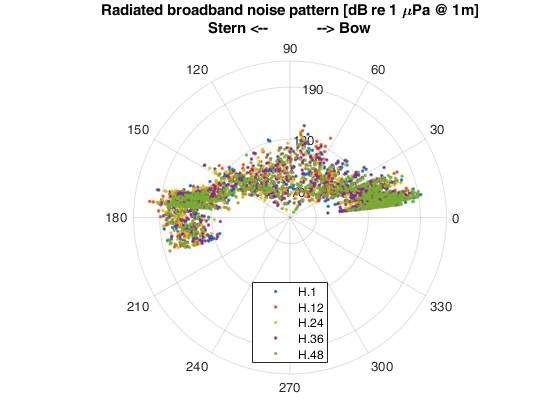

int.C150 = 541:551;
C150.max = zeros(NumSpec-2,NumRec);
C150.idx = zeros(NumSpec-2,NumRec);

for RecInd = 1:NumRec
    p = SL.ALL{RecInd,1}(:,int.C150);
    [C150.max(:,RecInd),C150.idx(:,RecInd)] = max(p,[],2);
end

figure
polarscatter(SPL.rads2(:,1),C150.max(:,1),'.')
rlim([165 195])
title({'Radiated broadband noise pattern [dB re 1 \muPa @ 1m]';...
    'Stern <--            --> Bow'})
if NumRec == 48
    hold on
    polarscatter(SPL.rads2(:,12)',C150.max(:,12),'.')
    polarscatter(SPL.rads2(:,24)',C150.max(:,24),'.')
    polarscatter(SPL.rads2(:,36)',C150.max(:,36),'.')
    polarscatter(SPL.rads2(:,48)',C150.max(:,48),'.')
    legend('H.1','H.12','H.24','H.36','H.48','Location','south')
end

### Bin SL by aspects

figure
histogram(SL.broadband(1,:))
hold on
histogram(SL.broadband(2,:))

### Calculate spread over hydrophones

figure
histogram(SL.broadband(1,:))
hold on
histogram(SL.broadband(2,:))

## Junk

### Plot signal and SPL

% figure
% subplot(3,1,1)
%     plot(t,x(1))
%     axis tight
%     ylabel('pressure (Pa)')
% subplot(3,1,2)
%     plot(t,RL2(1))
%     axis tight
%     ylabel('spl (dB)')
% subplot(3,1,3)
%     plot(AIS.datetime,R2(:,1,1),'.');
%     datetick('x')
%     ylabel('Contact range (km)')

### Loop through array elements

% fileName = 'ArraySPLWindows.mat';
% matObj = matfile(fileName);
% matObj.Properties.Writable = true;
% matObj.RL1 = zeros(nsam,nch); matObj.RL2 = zeros(nsam,nch);
% for ich = 1:nch
%     fprintf('Writing %d of %d\n',ich,nch);
%     RL2 = gain + spl(x(:,ich),'water',windowSize,fs);     % calculate SPL using spl sub-routine with 1-sec windows re 1uPa
%     matObj.RL2(:,ich) = RL2;
% end
%
% %RL = table(RL1,RL2);
% %RLtime = array2timetable(RL,'RowTimes',t);   %could shorten this
%

### Plot lobing pattern

% figure
% polarpattern(SPL.aspect2,SPL.SL2,'TitleTop', 'Radiated noise pattern (dB)')
% figure
% polarscatter(SPL.rads2,SPL.SL2)
% title('Radiated noise pattern (dB)')
%
% R =  cell(NumRec,1); % Range and bearing for each array element
% for RecInd=1:NumRec
%     R{RecInd} = zeros(NumSpec-2,2);
% end

### Loop to read data piece by piece

% for EventIndex = 1:(NumSpec-2)
%     for RecInd=1:NumRec
%         R{RecInd}(EventIndex,:) = 0;
%     end
% end